addpath('../');

jiro_pos={};
W=dir('jiro_pos/');
for j=1:size(W)
    if (strfind(W(j).name,'.jpg'))
        fn=strcat('jiro_pos/',W(j).name);
        jiro_pos={jiro_pos{:} fn};
    end
end

jiro_test={};
W=dir('jiro_test/');
for j=1:size(W)
    if (strfind(W(j).name,'.jpg'))
        fn=strcat('jiro_test/',W(j).name);
        jiro_test={jiro_test{:} fn};
    end
end

ring_pos={};
W=dir('ring_pos/');
for j=1:size(W)
    if (strfind(W(j).name,'.jpg'))
        fn=strcat('ring_pos/',W(j).name);
        ring_pos={ring_pos{:} fn};
    end
end

ring_test={};
W=dir('ring_test/');
for j=1:size(W)
    if (strfind(W(j).name,'.jpg'))
        fn=strcat('ring_test/',W(j).name);
        ring_test={ring_test{:} fn};
    end
end

% それ以外用
random={};
W=dir('../bgimg/bgimg/');
for j=1:size(W)
    if (strfind(W(j).name,'.jpg'))
        fn=strcat('../bgimg/bgimg/',W(j).name);
        random={random{:} fn};
    end
end

学習: 二郎 (relevence)

テスト: 二郎(interesting)

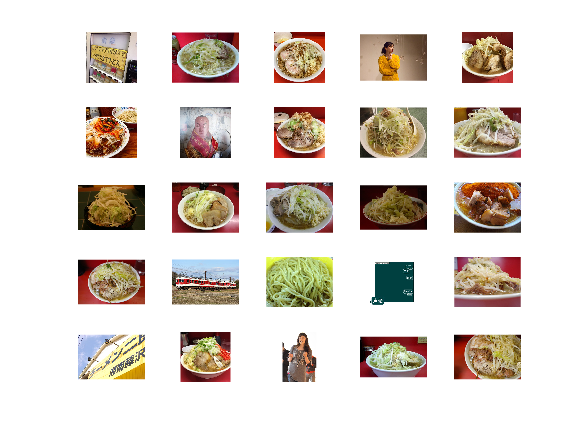

% テスト画像を確認
n=3;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(jiro_test{i+n*25}));
end

9+9+4+7=29個違う → 71/100

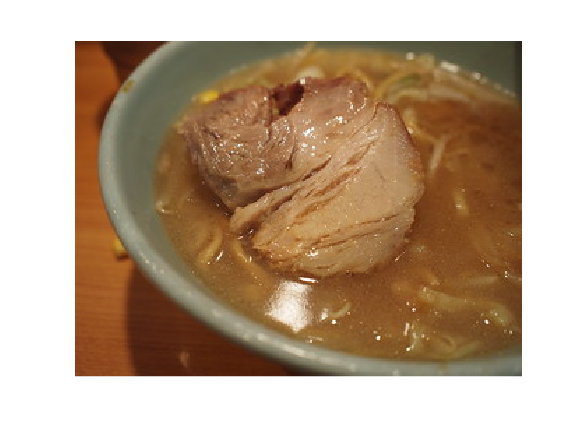

figure;clf;
imshow(imread(jiro_test{58}))

まずは25個で学習

n=25;
data_pos = jiro_pos(1:n);
data_neg = random(randperm(size(random,2),500));

train = [data_pos data_neg];
eval = jiro_test;

train_label=[ones(numel(data_pos),1); ones(numel(data_neg),1)*(-1)];

%  学習 
model = trainmodel(train, train_label, alexnet, 'fc7');
%　分類 
[plabel,score]=predictmodel(model, eval, alexnet, 'fc7');

% リランキング
FID = fopen('jiro_25.txt','w');
[sorted_score,sorted_idx] = sort(score(:,2),'descend');
for i=1:numel(sorted_idx)
    fprintf('%s %f\n',eval{sorted_idx(i)},sorted_score(i));
    fprintf(FID,'%s %.5f\n',eval{sorted_idx(i)},sorted_score(i));
end

jiro_test/0197.jpg -0.978103
jiro_test/0089.jpg -0.979126
jiro_test/0211.jpg -0.979127
jiro_test/0132.jpg -0.979431
jiro_test/0172.jpg -0.979465
jiro_test/0087.jpg -0.980072
jiro_test/0059.jpg -0.980149
jiro_test/0015.jpg -0.980176
jiro_test/0231.jpg -0.980411
jiro_test/0250.jpg -0.980422
jiro_test/0135.jpg -0.980546
jiro_test/0108.jpg -0.980902
jiro_test/0171.jpg -0.980980
jiro_test/0222.jpg -0.980995
jiro_test/0295.jpg -0.981052
jiro_test/0109.jpg -0.981309
jiro_test/0012.jpg -0.981408
jiro_test/0155.jpg -0.981422
jiro_test/0282.jpg -0.981424
jiro_test/0247.jpg -0.981441
jiro_test/0053.jpg -0.981693
jiro_test/0010.jpg -0.981831
jiro_test/0169.jpg -0.982118
jiro_test/0019.jpg -0.982149
jiro_test/0034.jpg -0.982168
jiro_test/0047.jpg -0.982305
jiro_test/0174.jpg -0.982369
jiro_test/0156.jpg -0.982586
jiro_test/0088.jpg -0.982621
jiro_test/0102.jpg -0.982720
jiro_test/0272.jpg -0.982991
jiro_test/0045.jpg -0.983135
jiro_test/0190.jpg -0.983395
jiro_test/0167.jpg -0.983407
jiro_test/0283

fclose(FID);

確認

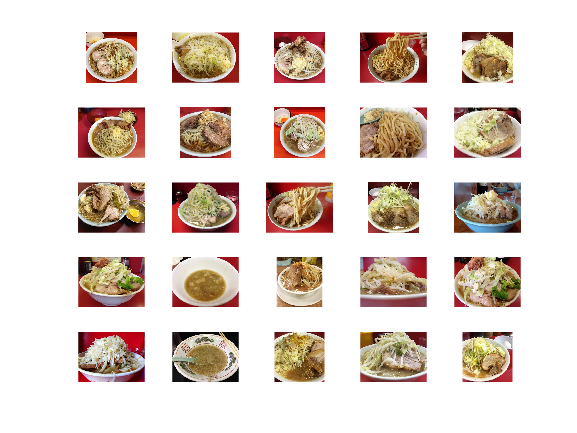

n=3;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(eval{sorted_idx(i+n*25)}));
end

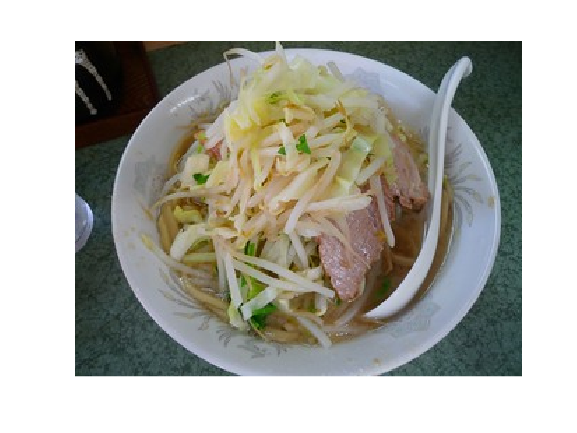

figure; clf;
imshow(imread(eval{sorted_idx(19)}));

100/100

50個で学習

n=50;
data_pos = jiro_pos(1:n);

train = [data_pos data_neg];
eval = jiro_test;

train_label=[ones(numel(data_pos),1); ones(numel(data_neg),1)*(-1)];

%  学習 
model = trainmodel(train, train_label, alexnet, 'fc7');
%　分類 
[plabel,score]=predictmodel(model, eval, alexnet, 'fc7');

% リランキング
FID = fopen('jiro_50.txt','w');
[sorted_score,sorted_idx] = sort(score(:,2),'descend');
for i=1:numel(sorted_idx)
    fprintf('%s %f\n',eval{sorted_idx(i)},sorted_score(i));
    fprintf(FID,'%s %.5f\n',eval{sorted_idx(i)},sorted_score(i));
end

jiro_test/0197.jpg -0.950228
jiro_test/0231.jpg -0.951698
jiro_test/0089.jpg -0.952942
jiro_test/0295.jpg -0.953349
jiro_test/0132.jpg -0.953933
jiro_test/0211.jpg -0.954116
jiro_test/0172.jpg -0.954702
jiro_test/0087.jpg -0.955406
jiro_test/0247.jpg -0.955840
jiro_test/0250.jpg -0.956289
jiro_test/0015.jpg -0.956303
jiro_test/0059.jpg -0.957163
jiro_test/0222.jpg -0.957202
jiro_test/0135.jpg -0.957427
jiro_test/0171.jpg -0.957866
jiro_test/0108.jpg -0.958120
jiro_test/0109.jpg -0.958340
jiro_test/0155.jpg -0.958765
jiro_test/0010.jpg -0.958887
jiro_test/0169.jpg -0.959184
jiro_test/0012.jpg -0.959219
jiro_test/0282.jpg -0.959519
jiro_test/0283.jpg -0.959538
jiro_test/0262.jpg -0.960448
jiro_test/0019.jpg -0.960948
jiro_test/0053.jpg -0.960992
jiro_test/0174.jpg -0.961081
jiro_test/0103.jpg -0.961137
jiro_test/0034.jpg -0.961234
jiro_test/0114.jpg -0.961457
jiro_test/0047.jpg -0.961779
jiro_test/0258.jpg -0.961886
jiro_test/0251.jpg -0.962095
jiro_test/0102.jpg -0.962310
jiro_test/0154

fclose(FID);

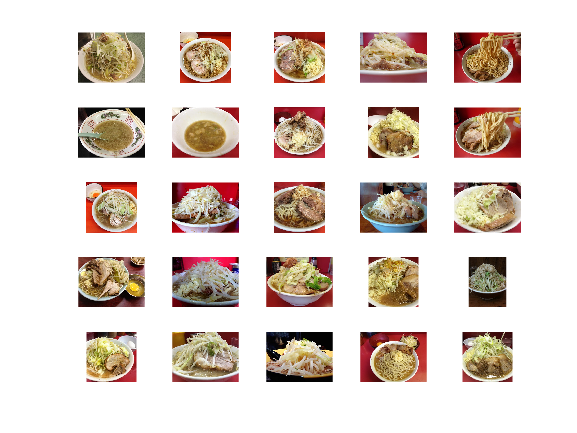

n=3;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(eval{sorted_idx(i+n*25)}));
end

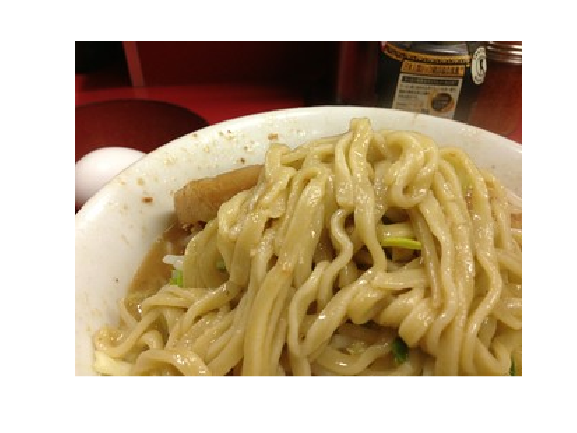

figure; clf;
imshow(imread(eval{sorted_idx(49)}));

100/100

学習: ring (relevance)

テスト: diamond ring(interesting)

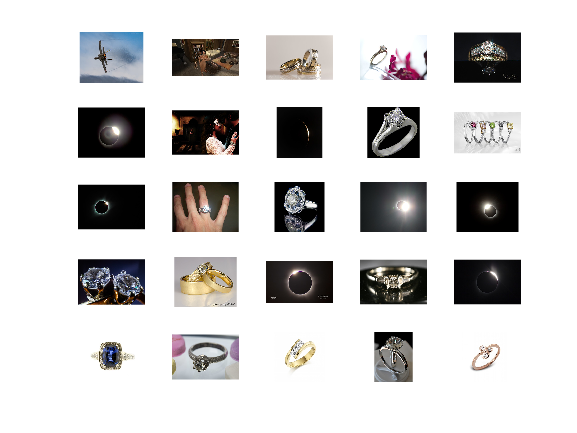

n=3;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(ring_test{i+n*25}));
end

12+17+13+15=57/100

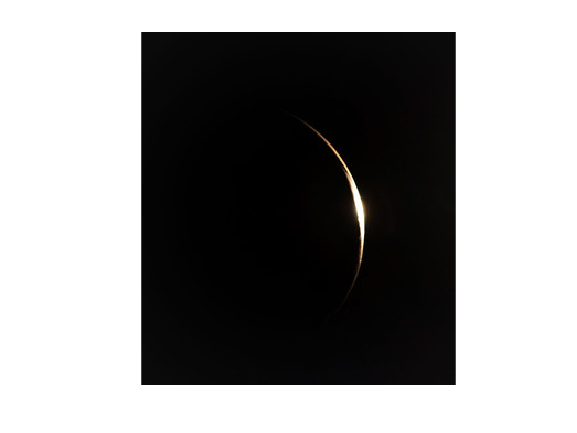

figure;clf;
imshow(imread(ring_test{83}))

25個で

n=25;
data_pos = ring_pos(1:n);
train = [data_pos data_neg];
eval = ring_test;

train_label=[ones(numel(data_pos),1); ones(numel(data_neg),1)*(-1)];

%  学習 
model = trainmodel(train, train_label, alexnet, 'fc7');
%　分類 
[plabel,score]=predictmodel(model, eval, alexnet, 'fc7');

% リランキング
FID = fopen('ring_25.txt','w');
[sorted_score,sorted_idx] = sort(score(:,2),'descend');
for i=1:numel(sorted_idx)
    fprintf('%s %f\n',eval{sorted_idx(i)},sorted_score(i));
    fprintf(FID,'%s %.5f\n',eval{sorted_idx(i)},sorted_score(i));
end

ring_test/0214.jpg -0.984434
ring_test/0143.jpg -0.984669
ring_test/0252.jpg -0.985189
ring_test/0254.jpg -0.985667
ring_test/0164.jpg -0.985992
ring_test/0142.jpg -0.986274
ring_test/0028.jpg -0.986767
ring_test/0189.jpg -0.986773
ring_test/0132.jpg -0.986776
ring_test/0248.jpg -0.987280
ring_test/0155.jpg -0.987687
ring_test/0162.jpg -0.988152
ring_test/0296.jpg -0.988193
ring_test/0215.jpg -0.988341
ring_test/0288.jpg -0.988443
ring_test/0209.jpg -0.988559
ring_test/0222.jpg -0.988649
ring_test/0113.jpg -0.988879
ring_test/0285.jpg -0.989102
ring_test/0277.jpg -0.989162
ring_test/0219.jpg -0.989162
ring_test/0049.jpg -0.989183
ring_test/0266.jpg -0.989251
ring_test/0240.jpg -0.989287
ring_test/0242.jpg -0.989303
ring_test/0179.jpg -0.989331
ring_test/0264.jpg -0.989511
ring_test/0110.jpg -0.989549
ring_test/0180.jpg -0.989596
ring_test/0047.jpg -0.989600
ring_test/0231.jpg -0.989849
ring_test/0299.jpg -0.990065
ring_test/0237.jpg -0.990074
ring_test/0167.jpg -0.990144
ring_test/0119

fclose(FID);

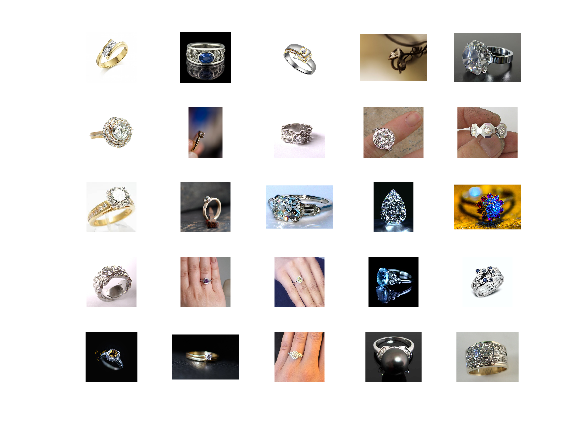

n=3;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(eval{sorted_idx(i+n*25)}));
end

95/100

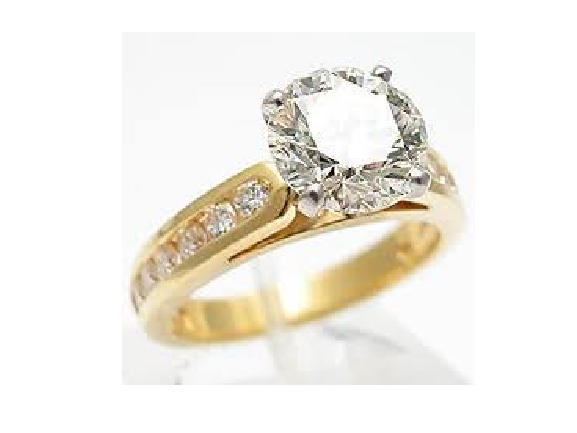

figure; clf;
imshow(imread(eval{sorted_idx(86)}));

n=50;
data_pos = ring_pos(1:n);

train = [data_pos data_neg];
eval = ring_test;

train_label=[ones(numel(data_pos),1); ones(numel(data_neg),1)*(-1)];

%  学習 
model = trainmodel(train, train_label, alexnet, 'fc7');
%　分類 
[plabel,score]=predictmodel(model, eval, alexnet, 'fc7');

% リランキング
FID = fopen('ring_50.txt','w');
[sorted_score,sorted_idx] = sort(score(:,2),'descend');
for i=1:numel(sorted_idx)
    fprintf('%s %f\n',eval{sorted_idx(i)},sorted_score(i));
    fprintf(FID,'%s %.5f\n',eval{sorted_idx(i)},sorted_score(i));
end

ring_test/0214.jpg -0.961483
ring_test/0143.jpg -0.962868
ring_test/0142.jpg -0.964704
ring_test/0252.jpg -0.964969
ring_test/0254.jpg -0.965798
ring_test/0164.jpg -0.966261
ring_test/0028.jpg -0.966402
ring_test/0132.jpg -0.966678
ring_test/0189.jpg -0.967372
ring_test/0248.jpg -0.968717
ring_test/0215.jpg -0.969170
ring_test/0209.jpg -0.969334
ring_test/0296.jpg -0.969997
ring_test/0155.jpg -0.970240
ring_test/0288.jpg -0.970536
ring_test/0179.jpg -0.970668
ring_test/0222.jpg -0.970817
ring_test/0110.jpg -0.971287
ring_test/0285.jpg -0.971338
ring_test/0162.jpg -0.971472
ring_test/0113.jpg -0.972005
ring_test/0277.jpg -0.972653
ring_test/0266.jpg -0.973289
ring_test/0240.jpg -0.973515
ring_test/0219.jpg -0.973712
ring_test/0180.jpg -0.974421
ring_test/0242.jpg -0.974928
ring_test/0141.jpg -0.974961
ring_test/0264.jpg -0.975049
ring_test/0127.jpg -0.975155
ring_test/0049.jpg -0.975335
ring_test/0293.jpg -0.975573
ring_test/0149.jpg -0.975655
ring_test/0257.jpg -0.975866
ring_test/0119

fclose(FID);

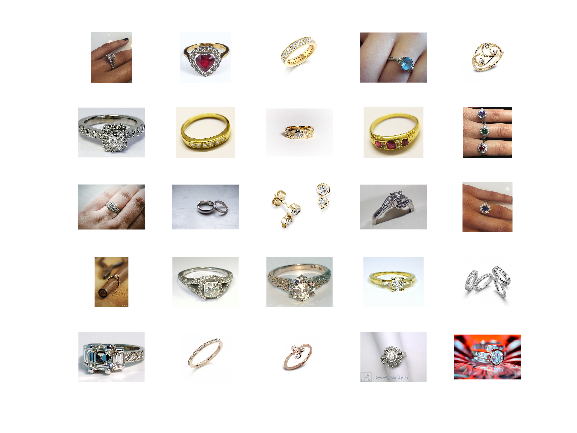

n=1;
figure; clf;
for i=1:25
    subplot(5,5,i);
    imshow(imread(eval{sorted_idx(i+n*25)}));
end

95/100

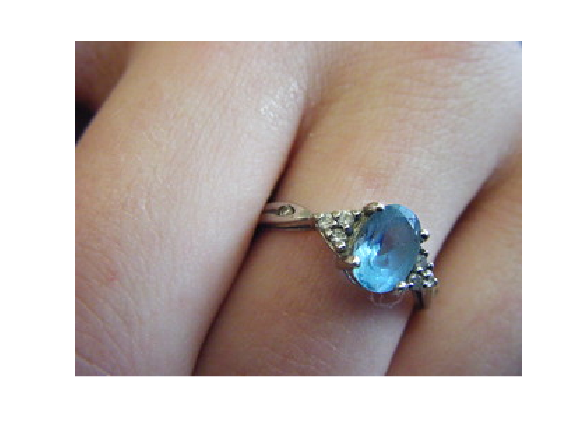

figure; clf;
imshow(imread(eval{sorted_idx(29)}));